# Optimization - full code

clc; clear; close all;

[param, weather, route, driver] = loadData();

effLoss = load("Inefficiency.mat").effLoss;
tempCF = load("temperatureCF.mat").tempCF;

cd("C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Codes\Optimization");

interestDay = datetime(2020,10,20);
enhanceFactor = 1.8;
raceDays = 5;
plotIsRequested = false;
weatherSim = weatherSimFullRace(interestDay, enhanceFactor, raceDays, plotIsRequested);

### Constant values

Colours for plots

colour = struct();
colour.loss = 'r';
colour.solar = 'g';
colour.battery = 'cyan';

Initial and safe to spend battery energy

SoCmin = 0.1;
Ebatmax = param.battery.Emax; %J
EbatSafe = Ebatmax * (1 - SoCmin); %J

Cumulative solar energy

EcumSolar = cumtrapz(weatherSim.irradiance.GtotalSec) * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total; %J
%%%%%%%%%%%%%%%%%%%%%%% CORRECTION FOR PLOTS
EcumSolar = EcumSolar * 1.1;

Roll force

Froll = param.constants.roll; %N

# Time

### First nights cut

horizon_8_17 = logical(weatherSim.irradiance.driving_8_17_Sec); %conversion to logical
Gtotal_8_17 = weatherSim.irradiance.GtotalSec(horizon_8_17);
dayNum_8_17 = weatherSim.irradiance.dayNumSec(horizon_8_17);
EcumSolar_8_17 = EcumSolar(horizon_8_17);

time_8_17 = weatherSim.irradiance.timeSec(horizon_8_17); %CHECK SHIFT BY ONE OF NIGHTS STOP FROM THE SECOND ONE
timeLen_8_17 = length(time_8_17);
timeSec_8_17 = linspace(1, timeLen_8_17, timeLen_8_17)';

### First guess velocity

horizon_unitedStops = timeSec_8_17 > (driver.numSpaceStops * seconds(minutes(30)));
EcumSolar_unitedStops = EcumSolar_8_17(horizon_unitedStops);
nightStopHour_unitedStops = (7 : 9 : (9*raceDays-1)) - driver.numSpaceStops * hours(minutes(30));
timeLen_unitedStops = timeLen_8_17 - driver.numSpaceStops * seconds(minutes(30)); %remove stop time
timeSec_unitedStops = linspace(1, timeLen_unitedStops, timeLen_unitedStops)';

[Ebudget_unitedStops, Eloss_unitedStops] = timeEnergyVariablesGenerator(timeSec_unitedStops, EcumSolar_unitedStops, EbatSafe);

[timeOpt_unitedStops, velMeanOpt_unitedStops] = optimalTimeVelocityEstimator(Eloss_unitedStops, Ebudget_unitedStops);

Optimal driving time: 29.41 h 
Optimal velocity: 102.93 km/h

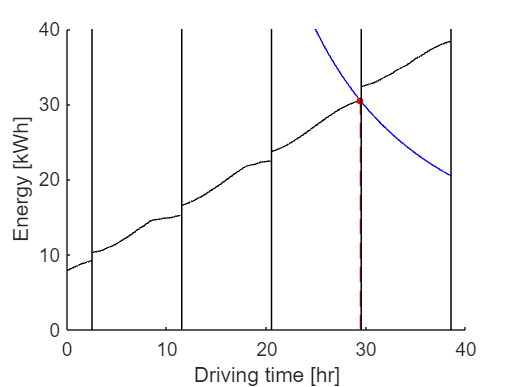

savePlots = false;
step = 32;

figure
hold on
plot(timeSec_unitedStops(1:step:end) / 3600, J2kWh(Ebudget_unitedStops(1:step:end)), 'k');
plot(timeSec_unitedStops(1:step:end) / 3600, J2kWh(Eloss_unitedStops(1:step:end)), 'b');
plot([timeOpt_unitedStops, timeOpt_unitedStops] / 3600, [0, J2kWh(Ebudget_unitedStops(timeOpt_unitedStops,1))], 'r--')
plot(timeOpt_unitedStops / 3600, J2kWh(Eloss_unitedStops(timeOpt_unitedStops)), 'r.', 'MarkerSize', 10)
plotLines(gca, 'vertical', nightStopHour_unitedStops, 'k')
ylabel("Energy [kWh]")
xlabel("Driving time [hr]")
ylim([0, 40])


if savePlots
    figureName = 'intersectionStrategyUnitedStopsError';
    latexMatlabPlotSaver(figureName, 'cleanFigure', true)
end % if

### Control stops cut

[timeSec_driving, controlStopBeginSec, finishSec, horizon_driving] = timeVecCreatorForPlots(velMeanOpt_unitedStops, timeSec_8_17);
controlStopBeginHour = controlStopBeginSec / 3600;
Gtotal_driving = Gtotal_8_17(horizon_driving);
dayNum_driving = dayNum_8_17(horizon_driving);
EcumSolar_driving = EcumSolar_8_17(horizon_driving);

[Ebudget_driving, Eloss_driving] = timeEnergyVariablesGenerator(timeSec_driving, EcumSolar_driving, EbatSafe);

### Night stops correction

space2time

[nightStopSec_17_cut] = space2timeNightsForPlots(controlStopBeginSec, raceDays);
nightStopHour_17_cut = nightStopSec_17_cut / 3600;

# Space

distM = timeSec_driving * velMeanOpt_unitedStops;
[EBatDist, ElossDist, EpotDist] = spaceEnergyVariablesGenerator(timeSec_driving, velMeanOpt_unitedStops, EcumSolar_driving);
SoCdist = EBatDist / Ebatmax;
EbudgetDist = Ebudget_driving;

### Night stops correction

time2space

nightStopDistM = nightStopSec_17_cut * velMeanOpt_unitedStops;
nightStopDistKm = nightStopDistM / 1000;

# Plots for the first guess

#### Time

subplot(2, 2, [1, 2]);
set(gca, 'ColorOrder', [0 0 0; 0 1 0], 'NextPlot', 'replacechildren');
timeAxisHour = timeSec_driving / 3600;
xlabel('Driving time [h]');

yyaxis left
hold on
xline(finishSec / 3600, 'k--', 'LineWidth', 1.2, 'HandleVisibility', 'off')
xline(timeOpt_unitedStops / 3600, 'r--', 'HandleVisibility', 'off')
xline(nightStopHour_17_cut, 'k', 'HandleVisibility', 'off')
xline(controlStopBeginHour, 'k--', 'HandleVisibility', 'off')
plot(timeAxisHour, J2kWh(Ebudget_driving), 'b', 'DisplayName', 'Total budget energy')
plot(timeAxisHour, J2kWh(EcumSolar_driving),'-','Color', [0 0.7 0.3], 'DisplayName', 'Cumulative solar energy')
plot(timeAxisHour, J2kWh(Eloss_driving), '-', 'Color', colour.loss, 'DisplayName', 'Energy loss')
plot(0, J2kWh(Ebatmax), '*', 'Color', colour.battery, 'MarkerSize', 5, 'DisplayName', 'Maximal battery energy')
plot(timeOpt_unitedStops / 3600, J2kWh(Eloss_driving(timeOpt_unitedStops)), 'r.', 'MarkerSize', 16, 'DisplayName', 'Optimum point')
ylabel('Energy [kWh]');
xlim([0, timeAxisHour(end)])
ylim([0, J2kWh(max(Ebudget_driving))]);

yyaxis right
plot(timeAxisHour, Gtotal_driving, 'Color', colour.solar, 'DisplayName', 'Solar irradiance')
ylabel('Irradiance [W/m^2]');
ylim([0, 1200]);

clickableLegend
legend('Location','northwest')
grid on
box on
hold off

#### Space

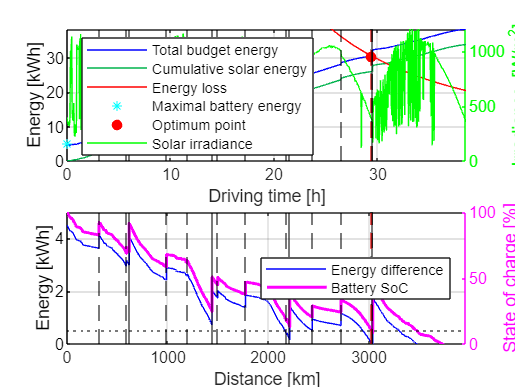

subplot(2, 2, [3, 4]);
set(gca, 'ColorOrder', [0 0 0; 1 0 1], 'NextPlot', 'replacechildren');
spaceAxisKm = distM / 1000;
xlabel('Distance [km]');

yyaxis left
hold on
xline(nightStopDistKm, 'k', 'HandleVisibility', 'off')
xline(driver.stopLocDist(2:end-1) / 1000, 'k--', 'HandleVisibility', 'off')
xline(driver.finishLocDist / 1000, 'k--', 'LineWidth', 1.2, 'HandleVisibility', 'off')
xline(velMeanOpt_unitedStops * timeOpt_unitedStops / 1000, 'r--', 'HandleVisibility', 'off')
plot(spaceAxisKm, J2kWh(EbudgetDist - ElossDist), 'b', 'DisplayName', 'Energy difference')
% plot(spaceAxisKm, J2kWh(EbudgetDist), 'b', 'DisplayName', 'Energy budget')
% plot(spaceAxisKm, J2kWh(EcumSolar_driving),'-','Color', [0 0.7 0.3], 'DisplayName', 'Cumulative solar energy')
% plot(spaceAxisKm, J2kWh(ElossDist), '-', 'Color', colour.loss, 'DisplayName', 'Energy loss')
% plot(spaceAxisKm, J2kWh(EBatDist), '-', 'Color', colour.battery, 'DisplayName', 'Battery energy')
ylabel('Energy [kWh]');
xlim([0, spaceAxisKm(end)])
% ylim([0, J2kWh(max(Ebudget_driving))]);
ylim([0, J2kWh(Ebatmax)]);

yyaxis right
yline((1 - EbatSafe / Ebatmax) * 100, 'k:', 'HandleVisibility', 'off')
plot(spaceAxisKm, SoCdist * 100, 'Color', 'm', 'LineWidth', 1.5, 'DisplayName', 'Battery SoC')
ylabel('State of charge [%]');
ylim([0, 100]);

clickableLegend
legend('Location','east')
grid on
box on
hold off

# Iteration

% lowSoCisDetected = min(SoCdist) < SoCmin; %assuming this happens before a night stop
% 
% if lowSoCisDetected
%     save("FullOptimizationVariables");
% 
%     segmentNum = raceDays;
%     velocityMean = ones(segmentNum, 1) * velMeanOpt_unitedStops; %initialize
%     velocityMean = iterativeDetector(velocityMean, segmentNum);
% end % if

# Functions

function [timeSec_driving, controlStopBeginSec, finishSec, horizon_driving] = timeVecCreatorForPlots(velocity, timeSec_8_17)
%with a given velocity we can cut the time plot corresponding to that specific stop location
    
persistent driver;
if isempty(driver)
    [~, ~, ~, driver] = loadData();
end % if

controlStopBeginSec = driver.stopLocDist(2:end-1) / velocity; %s ready to be plotted
finishSec = driver.stopLocDist(end) / velocity; %s
controlStopEndSec = controlStopBeginSec + seconds(minutes(30)); %s

horizon_controlStop = false(size(timeSec_8_17));
for i = 1:length(driver.stopLocDist(2:end-1))
    %accounting for previous stops
    tmp = (controlStopBeginSec(i) + (i-1)*seconds(minutes(30))) < timeSec_8_17 & timeSec_8_17 < (controlStopEndSec(i) + (i-1)*seconds(minutes(30))); %DANGER WHEN EQUAL? ONE SHOULD BE =
    horizon_controlStop = horizon_controlStop | tmp;
end % for

horizon_driving = ~horizon_controlStop;
time_driving = timeSec_8_17(horizon_driving);

timeLen_driving = length(time_driving);
timeSec_driving = linspace(1, timeLen_driving, timeLen_driving)';
end % fct

function [nightStopSec_17_cut] = space2timeNightsForPlots(controlStopBeginSec, raceDays)
%correct the night begin with the number of control stops
    
persistent driver;
if isempty(driver)
    [~, ~, ~, driver] = loadData();
end % if

controlStopBeginHour = controlStopBeginSec / 3600;
controlStopBeginWithNextControlStopHour = controlStopBeginHour + hours(minutes(30)) * (0 : length(controlStopBeginHour)-1)';
controlStopEndWithNextControlStopHour = controlStopBeginWithNextControlStopHour + hours(minutes(30));

nightStopHour_17_cut = (7 : 9 : 9*(raceDays))'; %initialize
idx = 1; %initialize
for j = 1:length(controlStopBeginHour)
    if nightStopHour_17_cut(idx) > controlStopBeginHour(j)
        nightStopHour_17_cut(idx) = nightStopHour_17_cut(idx) - hours(minutes(30));
    else %surpass night, idx increases by one and update the next night
        idx = idx + 1;
        nightStopHour_17_cut(idx) = nightStopHour_17_cut(idx) - j * hours(minutes(30));
    end % if
end % for
nightStopSec_17_cut = seconds(hours(nightStopHour_17_cut));


overlapNights = false(size(nightStopHour_17_cut)); %initialize
overlapSpaceStops = false(driver.numSpaceStops, 1); %initialize
for i = 1:length(nightStopHour_17_cut)
    overlapIsDetected = controlStopBeginWithNextControlStopHour < nightStopHour_17_cut(i) & nightStopHour_17_cut(i) <= controlStopEndWithNextControlStopHour; %DANGER WHEN EQUAL? ONE SHOULD BE =

    overlapSpaceStops = overlapSpaceStops | overlapIsDetected;
    overlapNights(i) = overlapNights(i) | boolean(sum(overlapIsDetected));
end % for
nightStopSec_17_cut(overlapNights == 1) = controlStopBeginSec(overlapSpaceStops == 1);
end % fct

function [EbudgetTime, ElossTime] = timeEnergyVariablesGenerator(time, EcumSolar, EbatSafe)
%with given time and velocity, it returns the useful energy quantities
    
persistent param;
persistent driver;
persistent effLoss;
if isempty(param)
    [param, ~, ~, driver] = loadData();
    effLoss = load("Inefficiency.mat").effLoss;
end % if

EbudgetTime = EcumSolar + EbatSafe;

Faero = param.constants.aero * (driver.finishLocDist ./ time).^2; %N
Froll = param.constants.roll; %N
ElossTime = driver.finishLocDist / effLoss * (Froll + Faero);
end % fct

function [EBatDist, ElossDist, EpotDist] = spaceEnergyVariablesGenerator(time, velocity, EcumSolar_driving)
%with given time and velocity, it returns the useful energy quantities
    
persistent param;
persistent route;
persistent effLoss;
if isempty(param)
    [param, ~, route, ~] = loadData();
    effLoss = load("Inefficiency.mat").effLoss;
end % if

distVec = time * velocity;

altiInterp = interp1(route.dist, route.alti, distVec);
EpotDist = param.constants.gravity * altiInterp; %J

FaeroDist = param.constants.aero * velocity.^2; %N
Froll = param.constants.roll; %N
ElossDist = distVec / effLoss * (Froll + FaeroDist); %J

Ebatmax = param.battery.Emax; %J
EBatDist = Ebatmax + EcumSolar_driving - ElossDist; % - EpotDist
end % fct

TODO

function [velocityMean] = iterativeDetector(velocityMean, segmentNum)
load("FullOptimizationVariables.mat"); %slow/unelegant but useful to have all variables needed

numDayDetection = dayNum_8_17(SoCdist == min(SoCdist));

detectionNightIndex_17 = max(find(diff(weatherSim.irradiance.driving_8_17_Sec) == -1, numDayDetection, 'first'));
Esolar_nthDay = EcumSolar(detectionNightIndex_17);

p = param.constants.roll / param.constants.aero;
q = -effLoss * (EbatSafe + Esolar_nthDay) / (seconds(horus(9*numDayDetection)) * param.constants.aero);
velSafe = cardanoDepressed3rd(p, q);
end % fct